figure

img = rgb2gray(imread("grad.png"))

img = 8×8 uint8 matrix
     0   255   255   255   255   255   255   255
     0     0   255   255   255   255   255   255
     0     0     0   255   255   255   255   255
     0     0     0     0   255   255   255   255
     0     0     0     0     0   255   255   255
     0     0     0     0     0     0   255   255
     0     0     0     0     0     0     0   255
     0     0     0     0     0     0     0     0


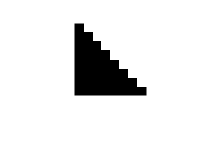

imshow(img, 'InitialMagnification', 1000);

Gx = imfilter(double(img), [-1, 0, 1], 'replicate')

Gx =    255   255     0     0     0     0     0     0
     0   255   255     0     0     0     0     0
     0     0   255   255     0     0     0     0
     0     0     0   255   255     0     0     0
     0     0     0     0   255   255     0     0
     0     0     0     0     0   255   255     0
     0     0     0     0     0     0   255   255
     0     0     0     0     0     0     0     0


Gy = imfilter(double(img), [-1, 0, 1]', 'replicate')

Gy =      0  -255     0     0     0     0     0     0
     0  -255  -255     0     0     0     0     0
     0     0  -255  -255     0     0     0     0
     0     0     0  -255  -255     0     0     0
     0     0     0     0  -255  -255     0     0
     0     0     0     0     0  -255  -255     0
     0     0     0     0     0     0  -255  -255
     0     0     0     0     0     0     0  -255


Gp = sqrt(Gx.*Gx + Gy.*Gy)

Gp =   255.0000  360.6245         0         0         0         0         0         0
         0  360.6245  360.6245         0         0         0         0         0
         0         0  360.6245  360.6245         0         0         0         0
         0         0         0  360.6245  360.6245         0         0         0
         0         0         0         0  360.6245  360.6245         0         0
         0         0         0         0         0  360.6245  360.6245         0
         0         0         0         0         0         0  360.6245  360.6245
         0         0         0         0         0         0         0  255.0000


Ga = rad2deg(atan2(Gy, Gx))

Ga =      0   -45     0     0     0     0     0     0
     0   -45   -45     0     0     0     0     0
     0     0   -45   -45     0     0     0     0
     0     0     0   -45   -45     0     0     0
     0     0     0     0   -45   -45     0     0
     0     0     0     0     0   -45   -45     0
     0     0     0     0     0     0   -45   -45
     0     0     0     0     0     0     0   -90


Ga(Ga < 0) = Ga(Ga < 0) + 180;
Ga(Ga == 180) = 0

Ga =      0   135     0     0     0     0     0     0
     0   135   135     0     0     0     0     0
     0     0   135   135     0     0     0     0
     0     0     0   135   135     0     0     0
     0     0     0     0   135   135     0     0
     0     0     0     0     0   135   135     0
     0     0     0     0     0     0   135   135
     0     0     0     0     0     0     0    90


Gd = round(Ga / 20);
Gd(Gd == 9) = 0

Gd =      0     7     0     0     0     0     0     0
     0     7     7     0     0     0     0     0
     0     0     7     7     0     0     0     0
     0     0     0     7     7     0     0     0
     0     0     0     0     7     7     0     0
     0     0     0     0     0     7     7     0
     0     0     0     0     0     0     7     7
     0     0     0     0     0     0     0     5


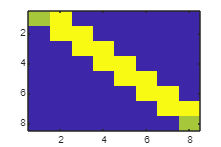

imagesc(Gp)

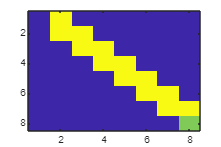

imagesc(Ga)

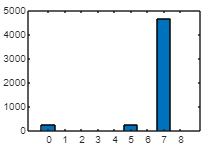

ids = 0:8;
sums = zeros(1, 9);
for i=ids
    sums(i+1) = sum(Gp(Gd == i));
end

bar(ids, sums)

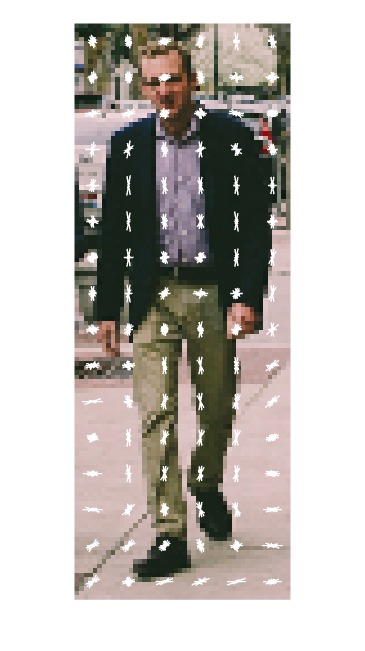

figure;
I1 = imread("person_1.jpg");
[hog1,vis1] = extractHOGFeatures(I1);
imshow(I1, 'InitialMagnification', 500); 
hold on;
plot(vis1);

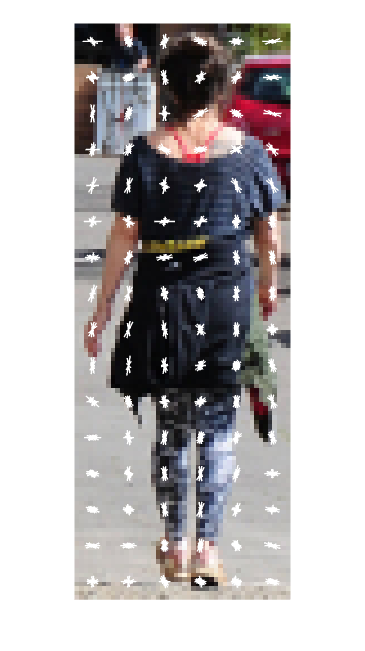

figure;
I2 = imread("person_2.jpg");
[hog2,vis2] = extractHOGFeatures(I2);
imshow(I2, 'InitialMagnification', 500); 
hold on;
plot(vis2);

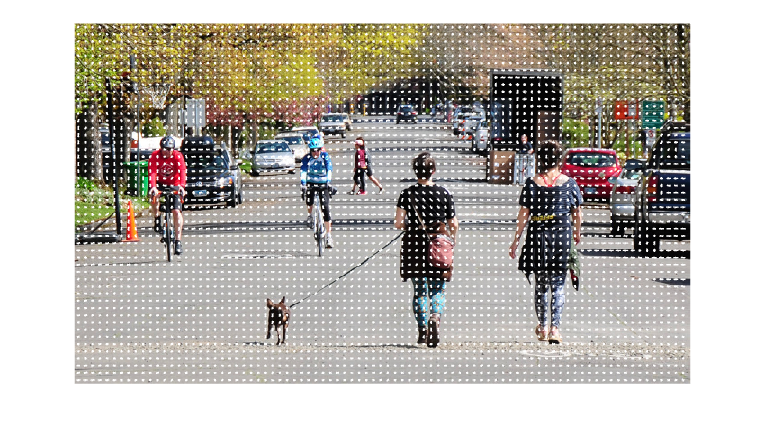

figure;
It = imread("people_1.jpg");
imshow(It);
hold on
[hogt,vist] = extractHOGFeatures(It);
plot(vist)

scale = 1

count_x = 77

count_y = 34

best_score = 1.6781

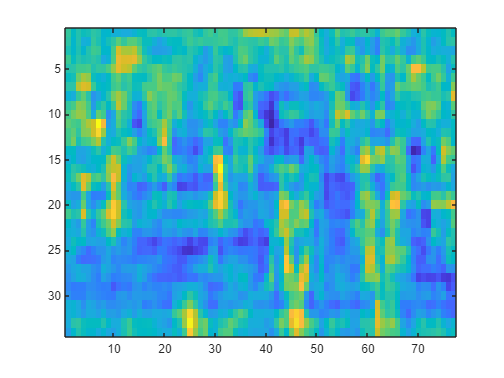

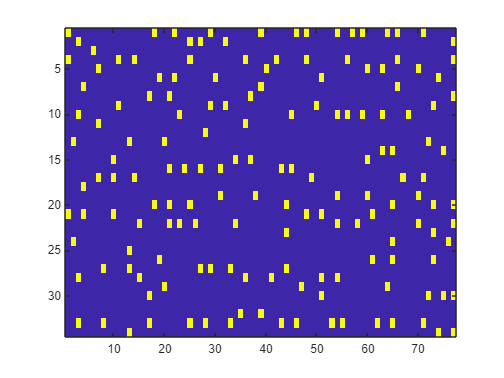

scale = 0.8000

count_x = 60

count_y = 24

best_score = 1.9233

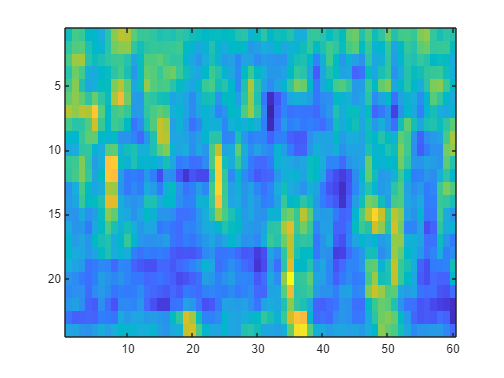

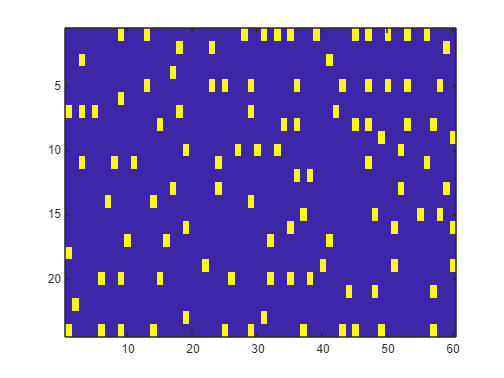

scale = 0.6400

count_x = 46

count_y = 16

best_score = 2.2756

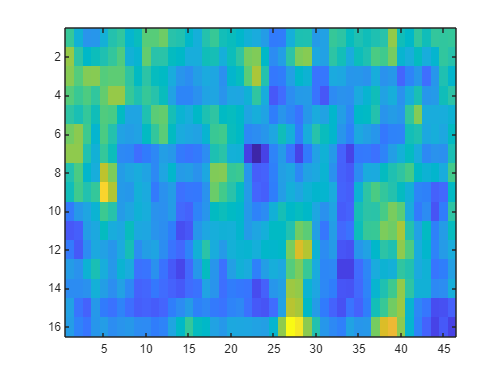

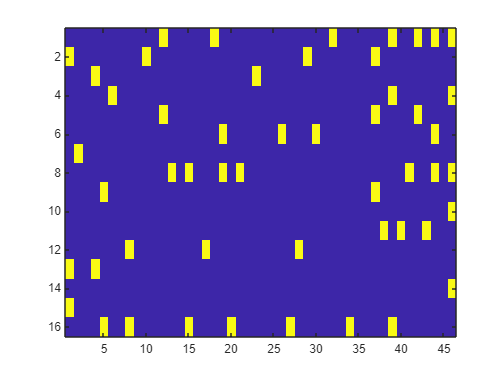

scale = 0.5120

count_x = 35

count_y = 9

best_score = 1.7438

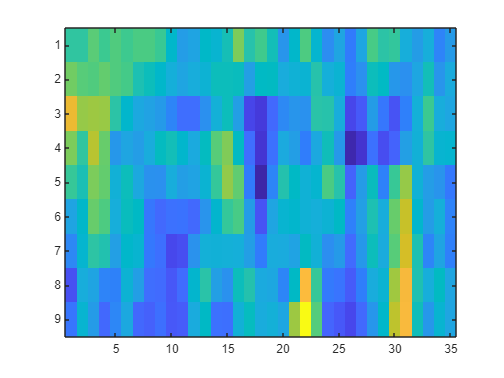

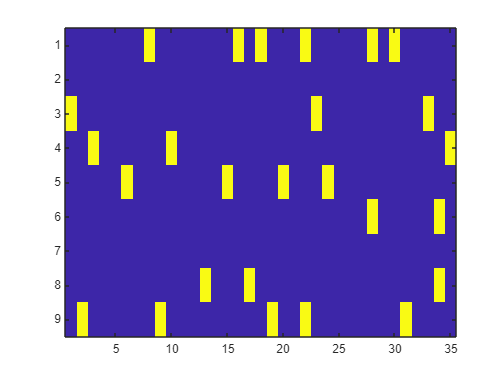

scale = 0.4096

count_x = 27

count_y = 4

best_score = 0.6601

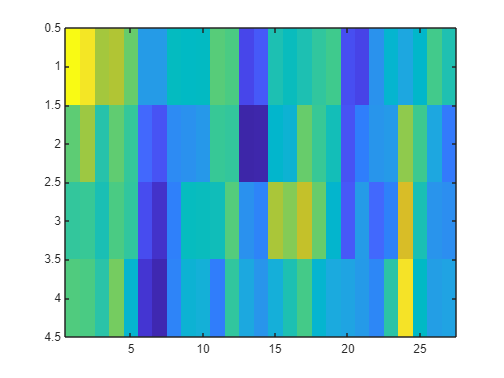

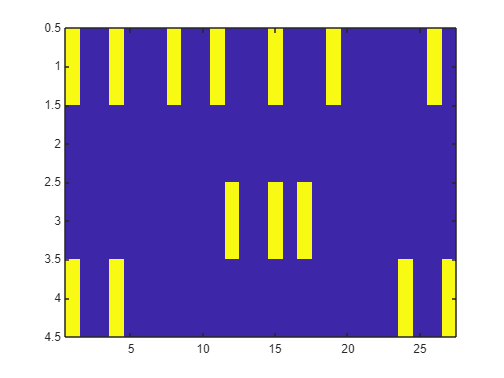

sx = 64;
sy = 128;
step = 8;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 60;

dets = [];
scores = [];
labels = {};

for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        sub_hog = extractHOGFeatures(sub_img);
        % klasyfikator
        % dist = min(sum((sub_hog - hog1) .^ 2 ), sum((sub_hog - hog2) .^ 2 ));
        
        [prediction, ~, posterior] = predict(model, sub_hog, 'Posterior', true);
        dist = posterior;
        out(j+1, i+1) = dist;
    end
end

best_score = max(max(out))

figure;
imagesc(out)
figure;
mins = imregionalmax(out);
mins(out > thr) = 0;
imagesc(mins);
[rs, cs] = find(mins);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;
    
    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

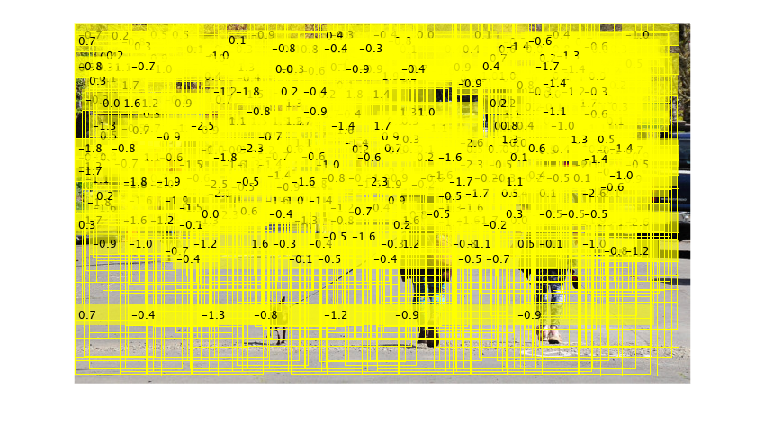

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

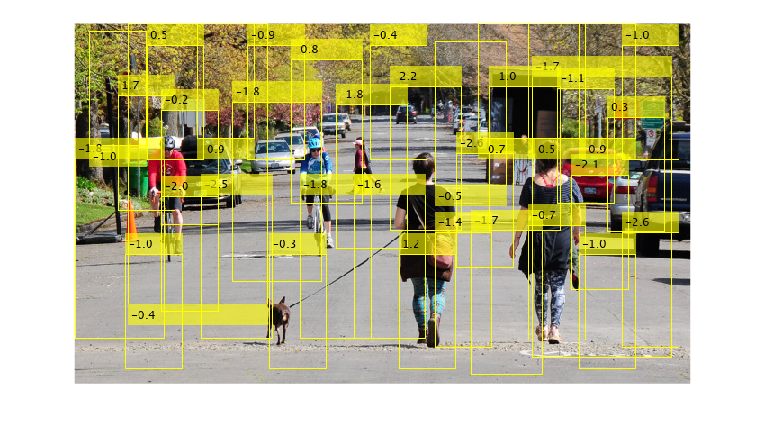

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

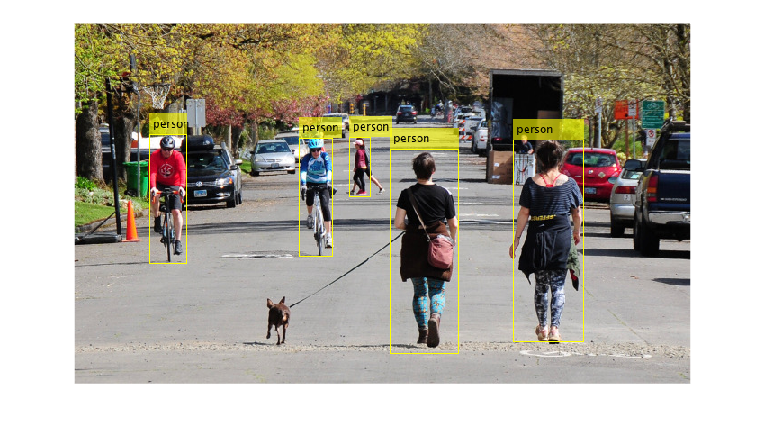

gt_rect=gTruth.LabelData.person{1,1};
ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);

score_thr = 30;
selected_dets = filtered_dets(filtered_scores < score_thr, :);
ratio = bboxOverlapRatio(gt_rect, selected_dets)

ratio =          0         0         0         0         0    0.1803    0.0827         0         0         0         0         0         0         0         0         0    0.0294         0         0         0         0         0         0         0         0         0         0         0         0    0.1239         0    0.2590         0    0.0935         0    0.2093
         0         0         0         0         0         0         0    0.1673    0.1590         0         0         0         0         0         0         0         0         0         0         0         0    0.0134         0    0.1844         0         0         0         0         0         0    0.0071         0         0         0         0         0
         0         0         0         0         0         0         0    0.0050         0    0.1256         0         0    0.0040         0         0         0         0         0         0         0         0         0         0    0.0750         0         0         0

[best_overlaps, good_ids] = max(ratio, [], 2)

best_overlaps =     0.2590
    0.1844
    0.1256
    0.3810
    0.4401


good_ids =     32
    24
    10
    35
    26


iou = 0.4;
best_ids = good_ids(best_overlaps > iou)

best_ids = 26

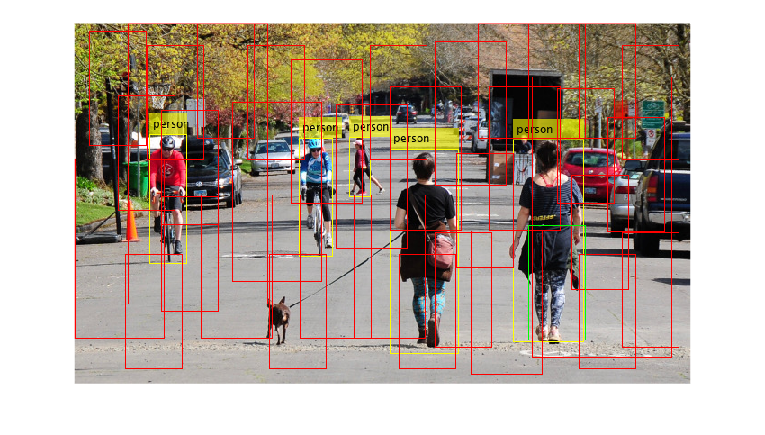

pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

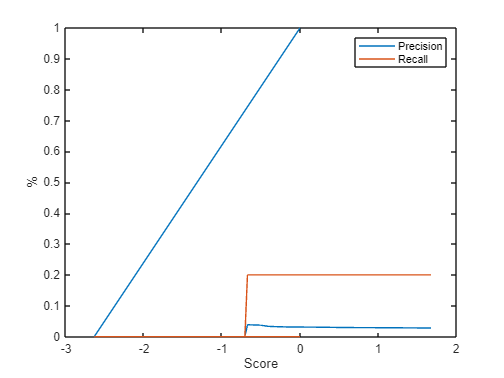

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");

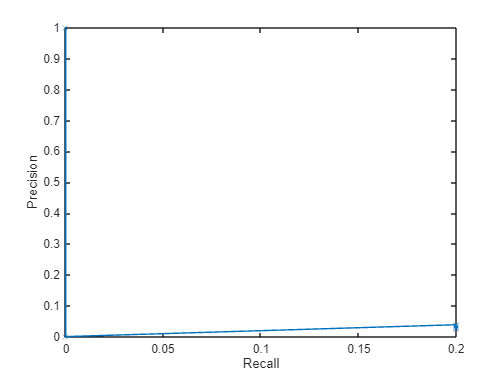

figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");

ap = trapz(R, P)

ap = 0.0038

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end